% Plant
L = 0.075;
R = 0.048;
Gp = tf([1], [L, R]);

% PI Controller
Kp = 1500;
Ki = 230000;
C = tf([Kp, Ki], [1, 0]);

% Open loop
OL = C * Gp;

% Closed loop (unity feedback)
CL = feedback(OL, 1);

% Step response info
info = stepinfo(CL, 'SettlingTimeThreshold', 0.02)

info = struct with fields:
         RiseTime: 1.0742e-04
    TransientTime: 1.8129e-04
     SettlingTime: 1.8129e-04
      SettlingMin: 0.9021
      SettlingMax: 1.0067
        Overshoot: 0.6716
       Undershoot: 0
             Peak: 1.0067
         PeakTime: 3.6895e-04


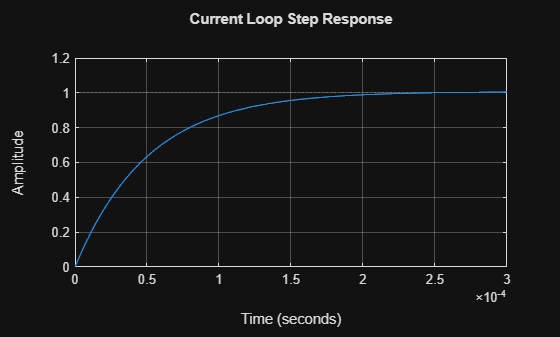


% Plot step response
figure
step(CL)
title('Current Loop Step Response')
grid on

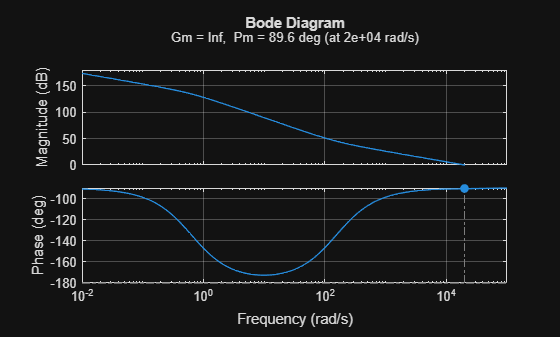


% Bode plot for phase/gain margin
figure
margin(OL)
grid on


% Check poles
poles = pole(CL)

poles = 1.0e+04 *

   -1.9846
   -0.0155



% Frequency response at 50Hz
w_50Hz = 2*pi*50;
[mag, phase] = bode(CL, w_50Hz);
fprintf('Gain at 50Hz: %.4f\n', mag)

Gain at 50Hz: 1.0061


fprintf('Phase at 50Hz: %.2f degrees\n', phase)

Phase at 50Hz: -0.73 degrees


fprintf('Settling time: %.4f seconds\n', info.SettlingTime)

Settling time: 0.0002 seconds


fprintf('Overshoot: %.2f%%\n', info.Overshoot)

Overshoot: 0.67%
